clear;
n=2;
coordinate=sym("u%d",[n,1]);
M=(1+coordinate(1)^2)^2;
g=[4/M,0;0 ,4*coordinate(1)^2/M];

uinterval=[-5,5];
vinterval=[0,2*pi];
hh=hjs("n",n,"coordinate",coordinate,"X",[coordinate(1);coordinate(2)],"g",g);
hh.g

$$ans = \left(\begin{array}{cc} \frac{4}{{\left({u_{1}}^{2}+1\right)}^{2}} & 0\\ 0 & \frac{4\,{u_{1}}^{2}}{{\left({u_{1}}^{2}+1\right)}^{2}} \end{array}\right)$$


hh();
hh.g

$$ans = \left(\begin{array}{cc} \frac{4}{{\left({u_{1}}^{2}+1\right)}^{2}} & 0\\ 0 & \frac{4\,{u_{1}}^{2}}{{\left({u_{1}}^{2}+1\right)}^{2}} \end{array}\right)$$

hh.connection

$$\left(\begin{array}{cc} -\frac{2\,u_{1}}{{u_{1}}^{2}+1} & 0\\ 0 & \frac{{\left({u_{1}}^{2}+1\right)}^{2}\,\left(\frac{8\,u_{1}}{{\left({u_{1}}^{2}+1\right)}^{2}}-\frac{16\,{u_{1}}^{3}}{{\left({u_{1}}^{2}+1\right)}^{3}}\right)}{8\,{u_{1}}^{2}} \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cc} 0 & -\frac{\sigma_{1}}{8}\\ \frac{\sigma_{1}}{8\,{u_{1}}^{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left({u_{1}}^{2}+1\right)}^{2}\,\left(\frac{8\,u_{1}}{{\left({u_{1}}^{2}+1\right)}^{2}}-\frac{16\,{u_{1}}^{3}}{{\left({u_{1}}^{2}+1\right)}^{3}}\right) \end{array}$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = 2$$

hh.Gauss_curvature

$$ans = 1$$

hh.drawmesh(uinterval,vinterval,0);
syms u(t)  T(t) [2,1] ;
interval=[0,2];
Init=[0.5, 0, 1,0 ];
ninterval=100;
         
            
            Y=sym('Y',[4,1]);
            coordinate=hh.coordinate;
            n=hh.n;
            X=hh.X;
            ss=hh.connection;
            sst=subs(ss,coordinate,u);
            dR=diff(u,1);
            T=dR;
            s1=diff(T,1)+squeeze(sum(repmat(reshape(T,1,n,1),[n,1,n]).* ...
                repmat(reshape(dR,1,1,n),[n,n,1]).*sst,[2,3]))==0

$$s1(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}u_{1}\left(t\right)-\frac{2\,u_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}u_{1}\left(t\right)\right)}^{2}}{{u_{1}\left(t\right)}^{2}+1}-\frac{\sigma_{1}\,\sigma_{2}\,{\left(\frac{\partial }{\partial t}u_{2}\left(t\right)\right)}^{2}}{8}=0\\ \frac{\partial^{2}}{\partial t^{2}}u_{2}\left(t\right)+\frac{\sigma_{1}\,\sigma_{2}\,\frac{\partial }{\partial t}u_{2}\left(t\right)\,\frac{\partial }{\partial t}u_{1}\left(t\right)}{4\,{u_{1}\left(t\right)}^{2}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{8\,u_{1}\left(t\right)}{\sigma_{2}}-\frac{16\,{u_{1}\left(t\right)}^{3}}{{\left({u_{1}\left(t\right)}^{2}+1\right)}^{3}}\\ \sigma_{2}={\left({u_{1}\left(t\right)}^{2}+1\right)}^{2} \end{array}$$

            simplify(s1)

$$ans(t) = \begin{array}{l} \left(\begin{array}{c} u_{1}\left(t\right)\neq -\mathrm{i}\wedge u_{1}\left(t\right)\neq \mathrm{i}\wedge u_{1}\left(t\right)\,\left(2\,{\left(\frac{\partial }{\partial t}u_{1}\left(t\right)\right)}^{2}+\sigma_{1}-{u_{1}\left(t\right)}^{2}\,\sigma_{1}\right)=\sigma_{2}\,\frac{\partial^{2}}{\partial t^{2}}u_{1}\left(t\right)\\ u_{1}\left(t\right)\neq 0\wedge u_{1}\left(t\right)\neq -\mathrm{i}\wedge u_{1}\left(t\right)\neq \mathrm{i}\wedge \left(u_{1}\left(t\right)\,\sigma_{2}\,\frac{\partial^{2}}{\partial t^{2}}u_{2}\left(t\right)=2\,\left({u_{1}\left(t\right)}^{2}-1\right)\,\frac{\partial }{\partial t}u_{1}\left(t\right)\,\frac{\partial }{\partial t}u_{2}\left(t\right)\vee u_{1}\left(t\right)=0\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}u_{2}\left(t\right)\right)}^{2}\\ \sigma_{2}={u_{1}\left(t\right)}^{2}+1 \end{array}$$

            [V,S]=odeToVectorField(s1)

$$V = \begin{array}{l} \left(\begin{array}{c} Y_{2}\\ \frac{{\left({Y_{3}}^{2}+1\right)}^{2}\,\sigma_{1}\,Y_{2}\,Y_{4}}{4\,{Y_{3}}^{2}}\\ Y_{4}\\ \frac{2\,Y_{3}\,{Y_{4}}^{2}}{{Y_{3}}^{2}+1}-\frac{{\left({Y_{3}}^{2}+1\right)}^{2}\,\sigma_{1}\,{Y_{2}}^{2}}{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{16\,{Y_{3}}^{3}}{{\left({Y_{3}}^{2}+1\right)}^{3}}-\frac{8\,Y_{3}}{{\left({Y_{3}}^{2}+1\right)}^{2}} \end{array}$$

$$S = \left(\begin{array}{c} u_{2}\\ {\mathrm{Du}}_{2}\\ u_{1}\\ {\mathrm{Du}}_{1} \end{array}\right)$$

            M=matlabFunction(V,'vars',{'t','Y'});
            syms u1 u2  Du1 Du2;
            yInit=matlabFunction(subs([u1;u2;Du1;Du2],S,Y));
            
            ySol = ode45(M,interval,yInit(Init(1),Init(2),Init(3),Init(4)))

ySol = 包含以下字段的 struct :
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2]
          y: [4×11 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


            tValues = linspace(interval(1),interval(2),ninterval);
            y=yInit(1 ,2 ,3, 4);
            yValues = deval(ySol,tValues,y(1:2))

yValues =      0   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
     1   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


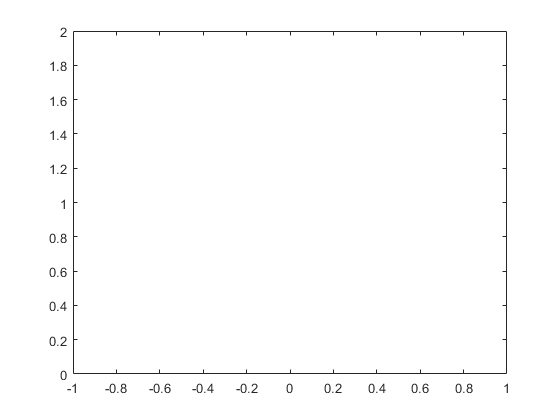

            y=matlabFunction(X);
            tt=y(yValues(1,:),yValues(2,:));
            
            if(size(tt,1)==2)
                plot(tt(1,:),tt(2,:));
            else
                plot3(tt(1,:),tt(2,:),tt(3,:),"LineWidth",2);
            end